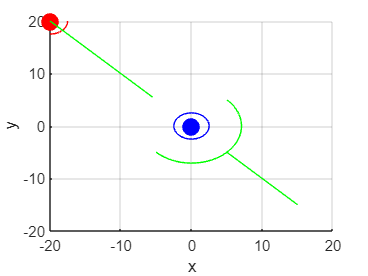

% USE OF THE NOTEBOOK
% This notebook is a simulation of air-conflict-resolution problem seen
% from a relative system.
% This code should work for every value of v, omega, phi with the
% assumption that linear and angular velocity are the same between the
% aircraft. Remember to check/change equation in state q2 ( solution of
% differential equation ).
% Ensure that hyperparameters ( velocities, times and relative velocity) are correct


% Point in which the simulation have been checked are
% P = [15, -15] / [15, -10] / [10; -15] / [ -15, 15 ]
% t = 2.29      /  2.0      /  2.0      / 1.5
% omega = 1     /  1        / -1        / 1

% cases: base_case / other example / base with negative omega / collision:
% too ealy manuver

% hyperparameters
syms t

protected_zone = 2.5;    % zone of protection
v = 5;                   % linear velocity of aircrafts
omega = 1;              % angualar velocity of aircrafts
phi = pi/2;              % angle difference on directions
init_state = [15; -15];  % afforable plot only if p_x = p_y

v1 = v;             % linear velocity of blue aircraft
v2 = v;             % linear velocity of red aircraft
omega1 = omega;     % angular velocity of blue aircraft
omega2 = omega;     % angular velocity of red aircraft
v_slope = v2/v1;         % slope of velocity seen from relative system
    
% hyperparameter of simulation: take from other script
t_switch_12 = 2;         % duration of state q1
t_switch_23 = pi/omega;     % duration of state q2
t_switch_3 = 0.3;           % duration of state q3
precision = 30;         % for plot
dt = 0.1;               % discretizing step
sim_pause = 0;          % DEPRECATED: was used to make simulation smooth
v_rel = [-v; v];        % relative velocity


% plot
figure;
grid on
hold on
xlabel('x');
ylabel('y');
xlim([-20, 20])
ylim([-20, 20])


% prepating object on the plot
theta = linspace(0, 2*pi, precision);       % discritizing circle equation
x1_circle = protected_zone * cos(theta);
y1_circle = protected_zone * sin(theta);
x2_circle = protected_zone * cos(theta);
y2_circle = protected_zone * sin(theta);

a1 = plot(0, 0, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');    % blue aircraft
a2 = plot(init_state(1), init_state(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % red aircraft
s1 = plot(x1_circle, y1_circle, 'b');   % protected zone of blue aircraft
s2 = plot(x2_circle + init_state(1), y2_circle + init_state(2), 'r');   % protected zone of red aircraft

current_x = init_state(1);
current_y = init_state(2);

% State q1
x_r_dot_q1 = -v1 + v2*cos(phi);
y_r_dot_q1 = v2*sin(phi);
phi_r_dot_q1 = 0;
state_q1_dot = [x_r_dot_q1; y_r_dot_q1];

x_r_q1 = int(x_r_dot_q1, t) + init_state(1);
y_r_q1 = int(y_r_dot_q1, t) + init_state(2);

% trajectory seen in relative system
t_q1 = linspace(0, t_switch_12, precision);     % discretizing trajectory
trajectory_q1 = plot( subs(x_r_q1, t, t_q1), subs(y_r_q1, t, t_q1), 'g' ); % plot of relative trajectory

for t1=1:length(t_q1)

    % update of position
    current_x = subs( x_r_q1, t, t_q1(t1) );
    current_y = subs( y_r_q1, t, t_q1(t1) );

    % update position of objectes
    set(a2, 'XData', current_x , 'YData', current_y ); 
    set(s2, 'XData', x2_circle + current_x, 'YData', y2_circle + current_y);

    pause(sim_pause)
end

% State q2
% Applying reset map
theta = pi/2;
rot = [cos(theta), -sin(theta); sin(theta), cos(theta)];

current_coordinate = rot * [current_x; current_y];
current_x = double( current_coordinate(1) );
current_y = double( current_coordinate(2) );

% NOTE: translation ( current_x, current_y ) is needed because other wise equation are the one
% finishing in (0,0)
x_r_q2 = -5 * cos(t) + 5 * sin(t) + 5 - current_x;
y_r_q2 = -5 * cos(t) - 5 * sin(t) + 5 - current_y;

% trajectory seen in relative system
t_q2 = linspace(0, t_switch_23, precision);   % discretizing
trajectory_q2 = plot( subs(x_r_q2, t, t_q2), subs(y_r_q2, t, t_q2), 'g' );

for t2=1:length(t_q2)
    
    % update position
    current_x = subs( x_r_q2, t, t_q2(t2) ); 
    current_y = subs( y_r_q2, t, t_q2(t2) );

    % update position of objectes
    set(a2, 'XData', current_x , 'YData', current_y );
    set(s2, 'XData', x2_circle + current_x, 'YData', y2_circle + current_y);

    pause(sim_pause)
end


% state_q3
% Applying reset map ( same of state q2 in this case )
current_coordinate = rot * [current_x; current_y];
current_x = current_coordinate(1);
current_y = current_coordinate(2);

% update position after reset map
set(a2, 'XData', current_x , 'YData', current_y );
set(s2, 'XData', x2_circle + current_x, 'YData', y2_circle + current_y);

t_q3 = linspace(0, t_switch_3, precision);

% calculating trajectory in advance
pos_x = current_x;
pos_y = current_y;
trajectory_q3_x = [];
trajectory_q3_y = [];

% calculating trajectory on state q3
for i=1:length(t_q3)

    pos_x = pos_x + v_rel(1)*dt;
    pos_y = pos_y + v_rel(2)*dt;

    trajectory_q3_x = [trajectory_q3_x, pos_x];
    trajectory_q3_y = [trajectory_q3_y, pos_y];
end

trajectory_q3 = plot( trajectory_q3_x, trajectory_q3_y, 'g' );

% see red aircraft mooving
for t3=1:length(t_q3)

    % update position
    current_x = current_x + v_rel(1)*dt;
    current_y = current_y + v_rel(2)*dt;

    % update position of objectes
    set(a2, 'XData', current_x , 'YData', current_y );
    set(s2, 'XData', x2_circle + current_x, 'YData', y2_circle + current_y);

    pause(sim_pause)
end